# Train a Model and Make Predictions

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads and displays the normalized (per minute) data set.

data = readtable("./data/bballTrainingData.xlsx", Sheet="data");
dataTrain = readtable("./data/bballTrainingData.xlsx", Sheet="dataTrain");
dataTest = readtable("./data/bballTrainingData.xlsx", Sheet="dataTest");
data

data = 609×22 table
      playerID                name               pos      height    weight     GP     minutes    points    oRebounds    dRebounds    rebounds    assists    steals    blocks    turnovers      PF      fgAttempted    fgMade    ftAttempted    ftMade    threeAttempted    threeMade
    _____________    ______________________    _______    ______    ______    ____    _______    ______    _________    _________    ________ 

whos

  Name             Size             Bytes  Class    Attributes

  data           609x22            317315  table              
  dataTest       182x20             52385  table              
  dataTrain      427x20            115879  table              



## Task 1

The normalized (per minute) numeric statistics from the basketball player data set has been divided into a training set `dataTrain` and a testing set `dataTest`. You will train a classification model using the training set, then make predictions for the testing set.

A *k-nearest neighbor* (kNN) model classifies an observation as the same class as the nearest known examples. You can fit a kNN model by passing a table of data to the `fitcknn` function.

`mdl` `=` `fitcknn``(``table``,``"ResponseVariable"``)`

The second input is the name of the response variable in the table (that is, the variable you want the model to predict). The output is a variable containing the fitted model.

knnmodel = fitcknn(dataTrain, "pos");

## Task 2

The `predict` function determines the predicted class of new observations.

`predClass` `=` `predict``(``model``,``newdata``)`

The inputs are the trained model and a table of observations, with the same predictor variables as was used to train the model. The output is a categorical array of the predicted class for each observation in `newdata`.

predPos = predict(knnmodel, dataTest);

## Task 3

How well did the kNN model predict player position?

A commonly-used metric to evaluate a model is the *misclassification rate* (the proportion of incorrect predictions). This metric is also called the model's *loss*.

You can use the `loss` function to calculate the misclassification rate for a data set.

`L` `=` `loss``(``model``,``table``)`

mdlLoss = loss(knnmodel, dataTest)

mdlLoss = 0.6322

## Task 4

The loss value indicates that over 60% of the positions were predicted incorrectly. Did the model misclassify some positions more than others?

A *confusion matrix* gives the number of observations from each class that are predicted to be each class. It's commonly visualized by shading the elements according to their value, with the diagonal elements (the correct classifications) shaded in one color and the other elements (the incorrect classifications) in another color. You can visualize a confusion matrix using the `confusionchart` function.

`confusionchart``(``ytrue``,``ypred``)``;`

`ytrue` is a vector of the known classes and `ypred` is a vector of the predicted classes.

The table `dataTest` contains the known player positions, which you can compare with the predicted positions, `predPos`.

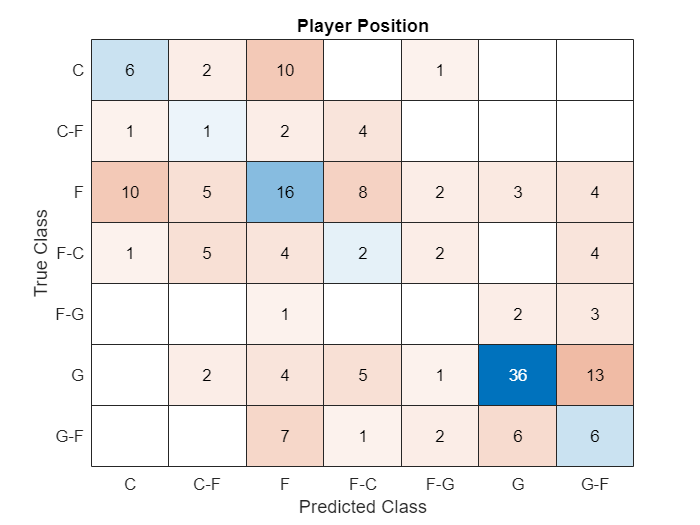

confusionchart(dataTest.pos, predPos);
title("Player Position")